%Export ground truth from image labeler (gTruth.mat is output)

load gTruth.mat

% create pixel label datastore

pxds = pixelLabelDatastore(gTruth);

%create pixel label image datastore for training

pximds = pixelLabelImageDatastore(imds,pxds);  %%%needs to be same number of files

%set training options

options = trainingOptions('sgdm','InitialLearnRate',1e-3, ...
    'MaxEpochs',20,'VerboseFrequency',10);

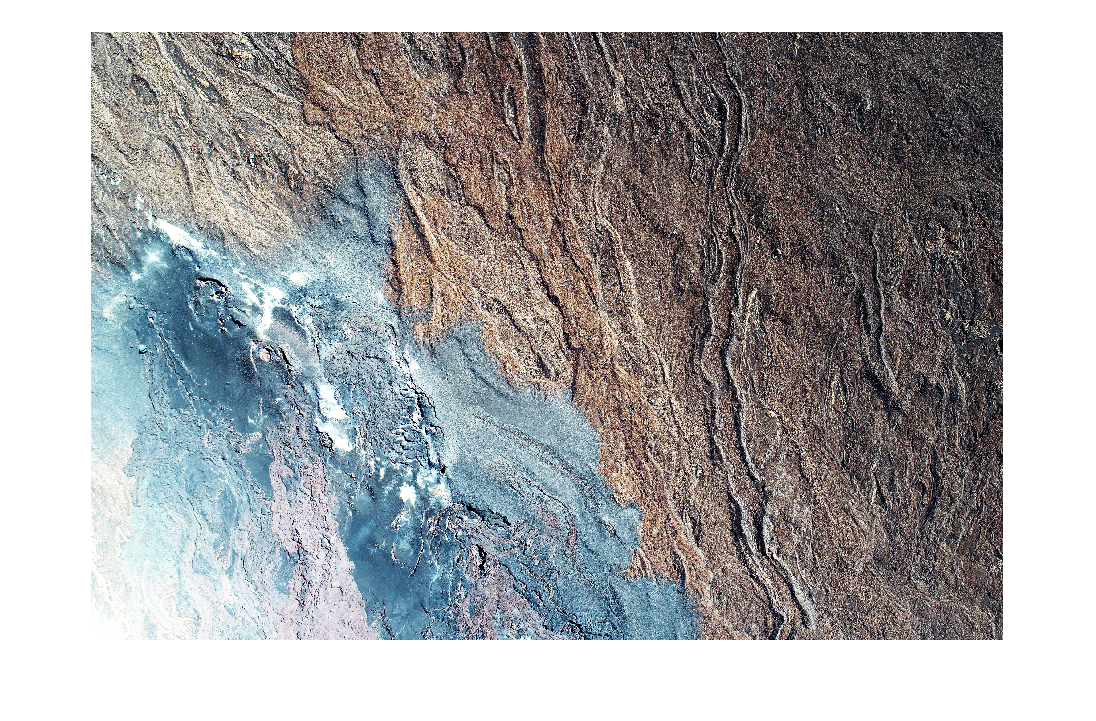

I = readimage(imds,1);
I = histeq(I);
imshow(I)

classes = galLabels{1:6,"Name"};

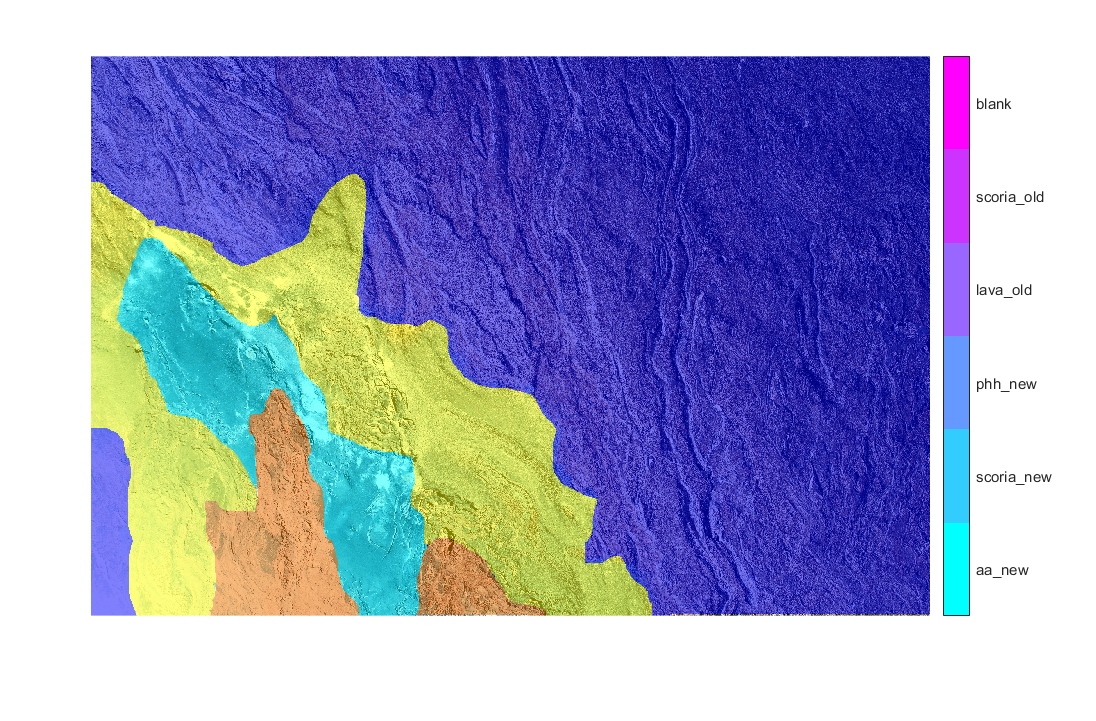

C = readimage(pxds,1);
B = labeloverlay(I,C);
imshow(B)

N = numel(classes);
ticks = 1/(N*2):1/N:1;
colorbar('TickLabels',cellstr(classes),'Ticks',ticks,'TickLength',0,...

    'TickLabelInterpreter','none');


cmap = 6×1 cell array
    {[1]}
    {[2]}
    {[3]}
    {[4]}
    {[5]}
    {[6]}


Error using colorbar (line 182)
Unrecognized input or invalid parameter/value pair arguments.

for i = 1:numel(imds)
    
    readimage(pxds,i)
  
    
end

ans = 3648×5472 categorical array
  Columns 1 through 642

     lava_old         lava_old         lava_old         lava_old         lava_old         lava_old         lava_old         lava_old         lava_old         lava_old         lava_old         lava_old         lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava_old      lava